## Input

input_path = 'D:\2020-11-23-Yichun\20201029_mouse_cerebellum\';
input_dim = [18560 3886 18];

% Load the images 
files = dir(fullfile(input_path, "*.tif"))

files = 5×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum



tic
rna_imgs = cell(4, 1);
goodPoints = cell(4, 1);

for c=1:4 
    curr_path = strcat(files(c).folder, '/', files(c).name);
    curr_img = new_LoadMultipageTiff(curr_path, 'uint8', 'uint8', false);
    
    % Thresholding
    curr_bw = (60 > curr_img) & (curr_img > 0);
    curr_img(curr_bw) = 0;
    
    exmax_bw = imextendedmax(curr_img, 100, 6);
    stats = regionprops3(exmax_bw, 'Centroid');
    curr_centroid = int16(stats.Centroid);
    goodPoints{c} = curr_centroid;
        
    rna_imgs{c} = curr_img;
    fprintf(sprintf('[time = %.2f s]\n', toc));
end

[time = 393.86 s]
[time = 804.40 s]
[time = 1204.36 s]
[time = 1615.05 s]


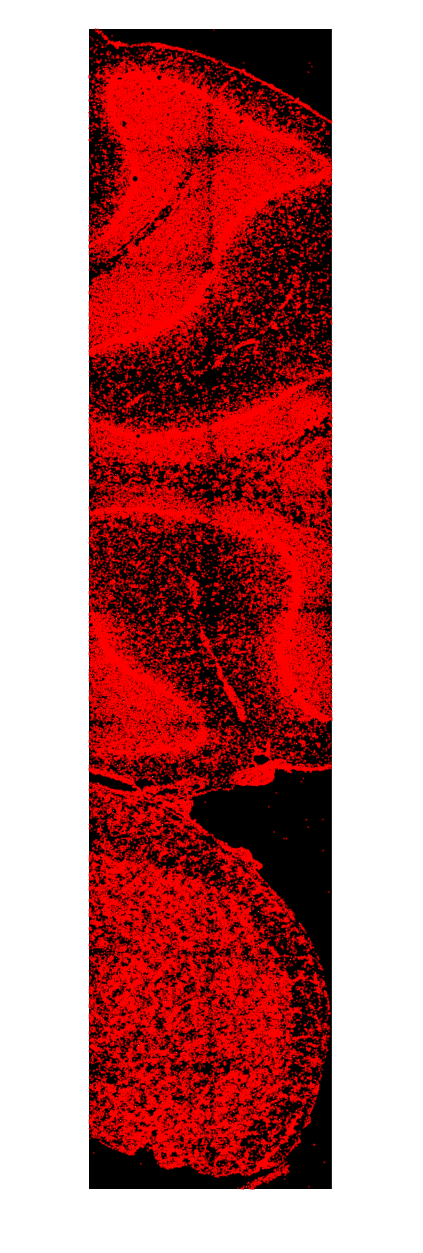

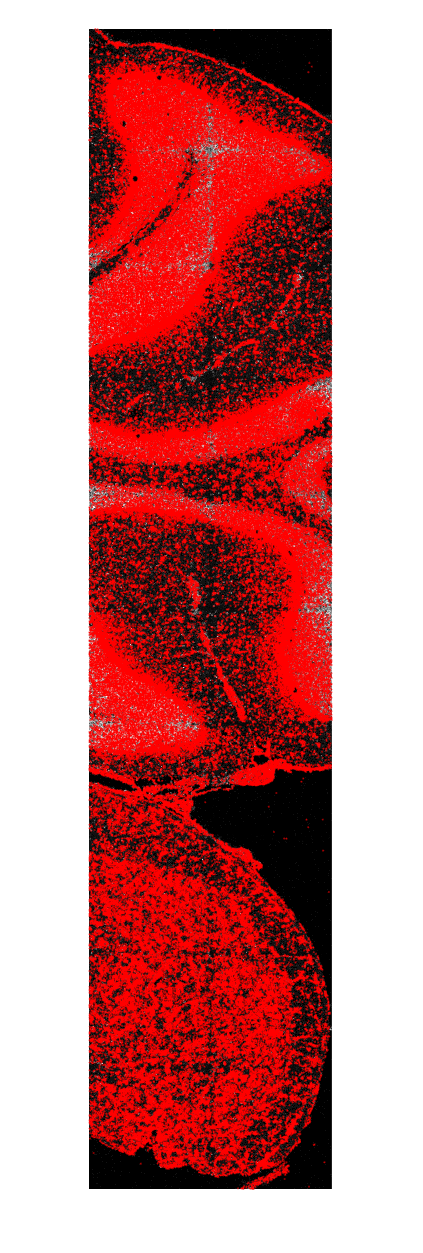

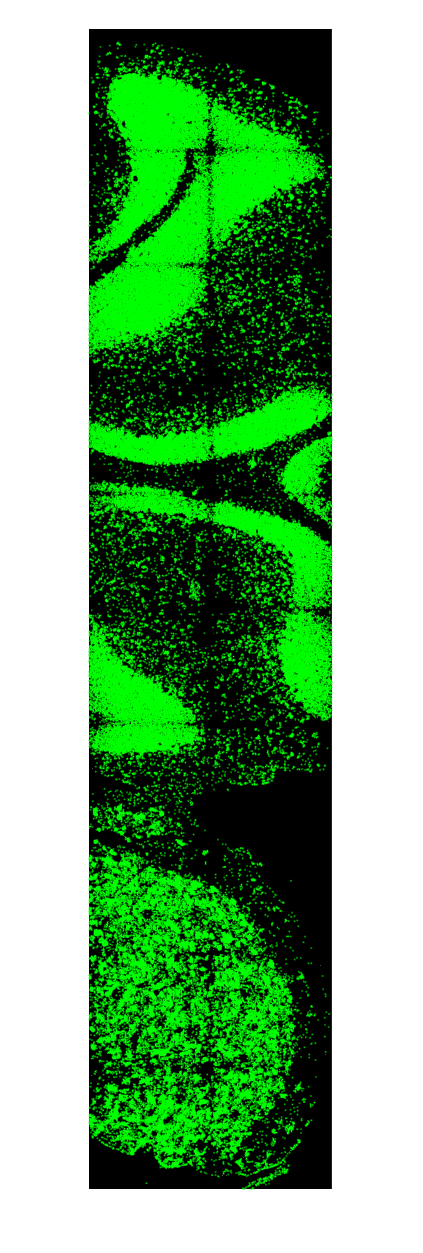

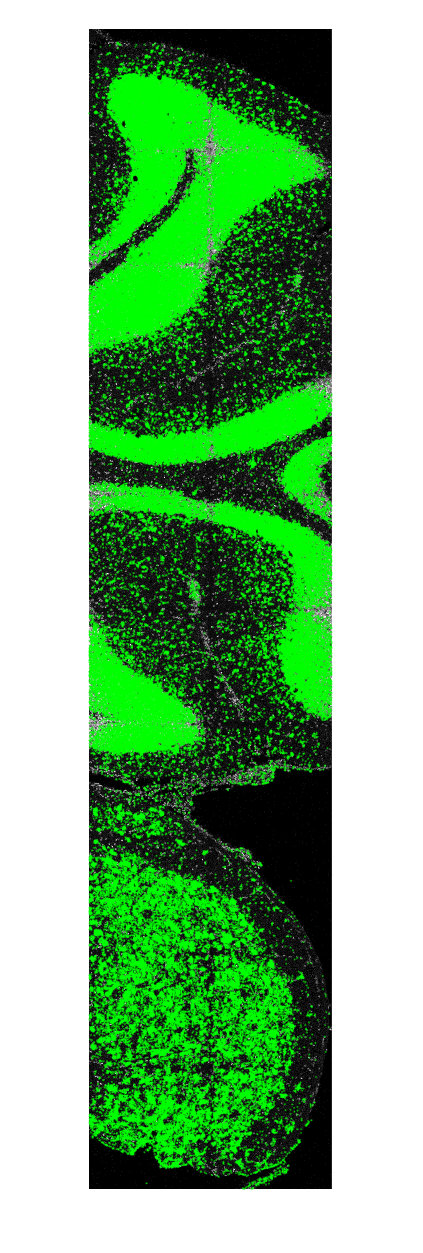

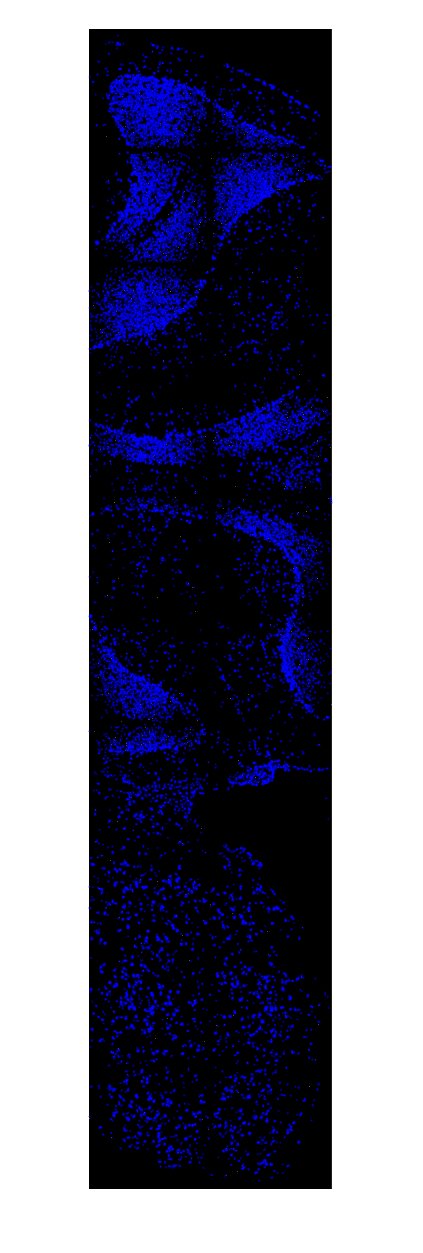

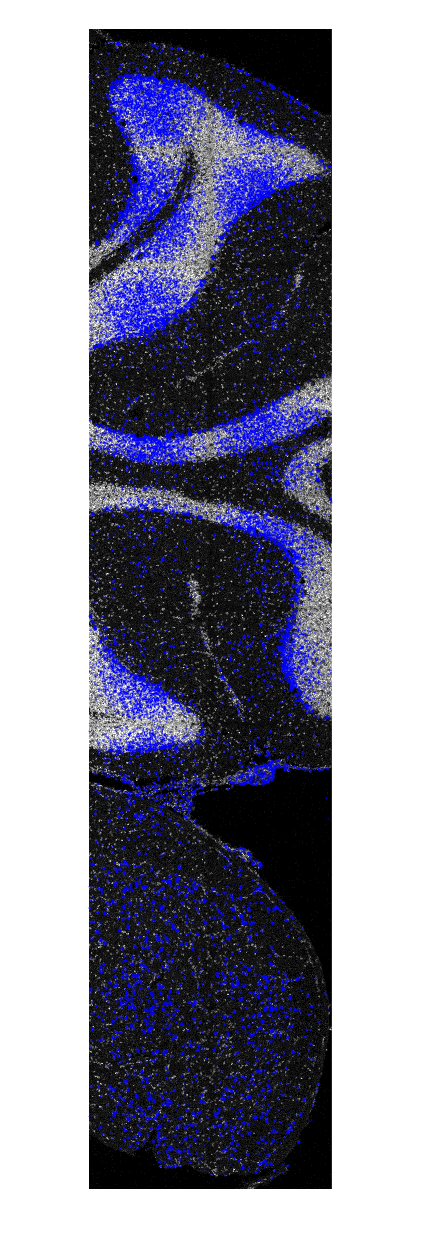

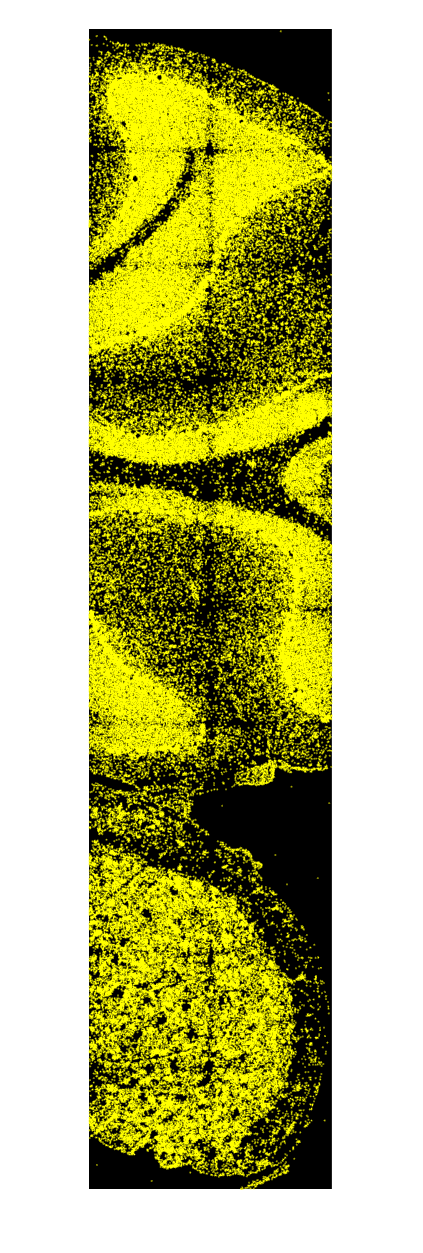

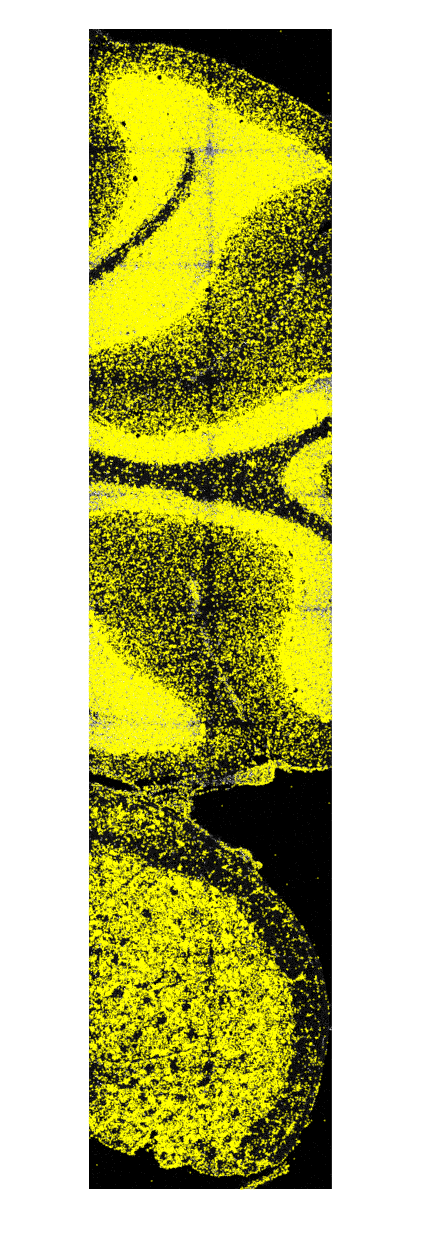


curr_out_path = fullfile(input_path, 'output');
if ~exist(curr_out_path, 'dir')
    mkdir(curr_out_path);
end

allPoints = [];
allReads = [];
genes = {'Actb', 'Snap25', 'Malat1', 'Calm1'}; 
colors = {'red', 'green', 'blue', 'yellow'};
for i=1:numel(goodPoints)
    gene = genes{i};
    
    curr_point = goodPoints{i};
    allPoints = [allPoints; curr_point];
    allReads = [allReads; ones(size(curr_point, 1), 1) * i];
    bk_img = max(rna_imgs{i}, [], 3);
    plot_centroids(curr_point, bk_img, 2, colors{i})
    fig_name = fullfile(curr_out_path, sprintf("%s_on_rna.png", gene));
    saveas(gcf, fig_name)
            
    bk_path = strcat(files(5).folder, '/', files(5).name);
    bk_img = new_LoadMultipageTiff(bk_path, 'uint8', 'uint8', false);
    bk_img = max(bk_img, [], 3);
    plot_centroids(curr_point, bk_img, 2, colors{i})
    
    fig_name = fullfile(curr_out_path, sprintf("%s_on_dapi.png", gene));
    saveas(gcf, fig_name)
end

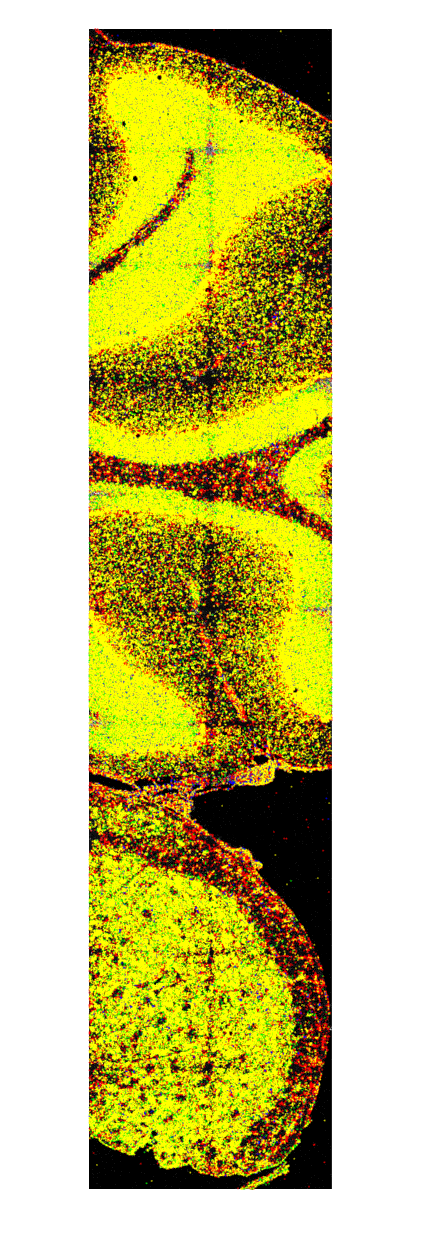



bk_path = strcat(files(5).folder, '/', files(5).name);
bk_img = new_LoadMultipageTiff(bk_path, 'uint8', 'uint8', false);
bk_img = max(bk_img, [], 3);
    
figure
imshow(bk_img)
hold on  
for i=1:numel(goodPoints)
    curr_point = goodPoints{i};
    plot(curr_point(:,1), curr_point(:,2), '.', "Color", colors{i}, "MarkerSize", 2)
end
hold off
fig_name = fullfile(curr_out_path, 'all_gene_on_dapi.png');
saveas(gcf, fig_name)


save(fullfile(curr_out_path, 'allPoints.mat'), 'allPoints', 'allReads');

## Preporcessing

% Thresholding


curr_bw = (50 > tdata.rawImages) & (tdata.rawImages > 0);
tdata.rawImages(curr_bw) = 0;



% se = strel('disk', 3);
% 
% for r=1:Nsamples
%     tic
%     fprintf(sprintf("Processing Sample %d...", r));
% 
%     for c=1:4
%         curr_channel = rna_imgs{r}(:,:,:,c);
%         Nslice = size(curr_channel, 3);
%         for z=1:Nslice
%             curr_slice = curr_channel(:,:,z);
%             % gaussian 
%             curr_slice = imgaussfilt(curr_slice, 1);
%             
%             marker = imerode(curr_slice, se); % Morphological opening is useful for removing small objects from an image while preserving the shape and size of larger objects in the image
%             obr = imreconstruct(marker, curr_slice);
%             curr_out = curr_slice - obr;
% 
%             curr_out = imsubtract(imadd(curr_out, imtophat(curr_out, se)), imbothat(curr_out, se));
%            
%             curr_channel(:,:,z) = curr_out;
%         end
%         rna_imgs{r}(:,:,:,c) = uint8(curr_channel);
%     end
%     fprintf(sprintf('[time = %.2f s]\n', toc));
% end 

## Spot Finding

goodPoints = {};

for i=1:Nsamples
    curr_sample = rna_imgs{i};
    for c=1:4
        tic
        curr_channel = curr_sample(:,:,:,c);
        exmax_bw = imextendedmax(curr_channel, 80, 6);
        stats = regionprops3(exmax_bw, 'Centroid');
        curr_centroid = int16(stats.Centroid);
        goodPoints{end+1} = curr_centroid;
        fprintf(sprintf('Sample %d - channel %d Finished [time = %.2f s]\n', i, c, toc));
    end
end

goodPoints_b3 = goodPoints(1:4);
goodPoints_c3 = goodPoints(5:8);

save(fullfile(input_path, 'output', 'goodPoints_b3.mat'), 'goodPoints_b3');
save(fullfile(input_path, 'output', 'goodPoints_c3.mat'), 'goodPoints_c3');

% Plot dots for B3
for i=1:numel(goodPoints_b3)
    curr_point = goodPoints_b3{i};
    curr_img = max(rna_imgs{1}(:,:,:,i), [], 3);
    plot_centroids(curr_point, curr_img)
end

% Plot dots for C3
for i=1:numel(goodPoints_c3)
    curr_point = goodPoints_c3{i};
    curr_img = max(rna_imgs{2}(:,:,:,i), [], 3);
    plot_centroids(curr_point, curr_img)
end